Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Octagonal BPM (Section 7.2)

Volker Ziemann, 211120

In this example we analyze the octagonal beam position monitor (BPM) shown in Figure 7.4 and calculate the signals on four electrodes for different position of a beam. Here we use the fact that the transverse fields of an ultra-relativistic beam are purely transverse and can be derived from solving the Poisson equation with the suitable boundary conditions. 

We start out by defining the geometry of the octagonal BPM as a polygon.

clear all;
bpm=[2; 8; -0.030;0.030;0.050;0.050;0.030;-0.030;-0.050;-0.050;  ...
  0.020;0.020;0.010;-0.010;-0.020;-0.020;-0.010;0.010];  % polygon

Then we use sliders to specify the position of the `beam` and define it as a circle with center at `dx` and `dy` and radius `0.001`. Note the padding with zeros in order to make the length of `bpm` and` beam` equal.

dx=0.01 % horizontal position of the beam

dx = 0.0100

dy=0 % vertical position of the beam

dy = 0

beam=[1;dx;dy;0.001;zeros(14,1)];  % circle

In the next step we assemble geometric data` gd,` give names to the regions, and specify the relation among the geometric base objects before assembling the geometry `g` and create the `model`. Then we add the gemetry to the model and prepare a plot in order to inspect the `EdgeLabels `and the `SubDomainLabels`.

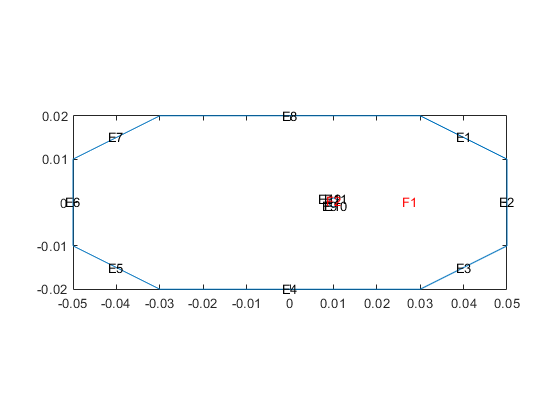

gd=[bpm,beam];           % assemble geometry
ns=char('bpm','beam')';  % names of the regions                 
sf='bpm+beam'; 
g=decsg(gd,sf,ns);
model=createpde(1);
geometryFromEdges(model,g);
pdegplot(model,'EdgeLabels','on','SubDomainLabels','on'); axis equal

Once we know the labels we can assign boundary conditions for the potential `u = `$\Phi(x,y)=0$ on the outer walls of the BPM, which are grounded. The volume of the BPM is just vacuum and characterized by` c=1`, whereas the charge of the beam enters the coefficient `f`.

applyBoundaryCondition(model,'Edge',[1:8],'u',0);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',0,'Face',1);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',5.6e9,'Face',2);

In the next step we generate the mesh with  a rather small mesh size, controlled by the parameter `Hmax`.

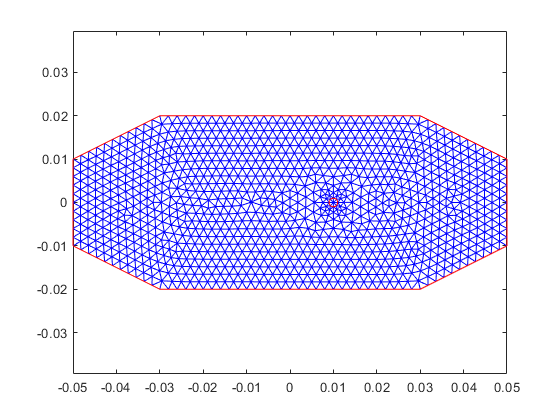

generateMesh(model,'Hmax',0.002); 
figure; pdemesh(model); axis equal;

Now we are ready to solve the problem and retreive the structure `result`. One of its members are the potential u = $\Phi(x,y)$, which is accessible as NodalSolution, while the electric field components $E_x$ and $E_y$ are available as the gradients.

result=solvepde(model); u=result.NodalSolution;
Ex=-result.XGradients; 
Ey=-result.YGradients; 
EE=hypot(Ex,Ey);

In order to prepare contour plots we need information about the points` p`, edges `e,` and triangles `t` of the mesh and obtain this with the function `meshToPet()`. Then we we prepare a plot to show the geometry and a contourplot of $E_y$. Moreover, we place resd asterieks at the positions of the electrodes.

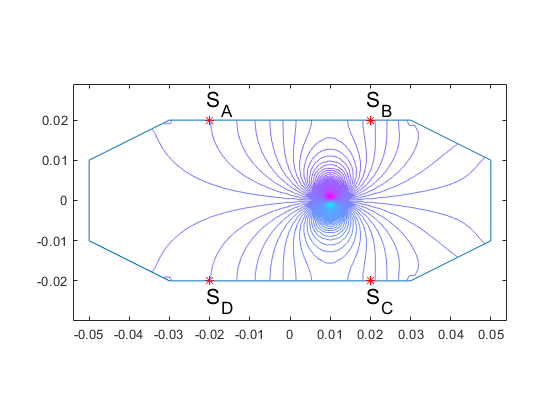

[p,e,t]=meshToPet(model.Mesh);  
figure; pdegplot(model); hold on; 
plot(-0.02,0.02,'r*',0.02,0.02,'r*',-0.02,-0.02,'r*',0.02,-0.02,'r*')
text(-0.021,0.024,'S_A','FontSize',16); text(0.019,0.024,'S_B','FontSize',16); 
text(-0.021,-0.025,'S_D','FontSize',16); text(0.019,-0.025,'S_C','FontSize',16); 
pdecont(p,t,Ey,200); axis([-0.054,0.054,-0.0299,0.0289]);

Now we evaluate the field components at the locations of the four electrodes $S_A, S_B,S_C$ and $S_D$ and define the signal as the absolute value of the electric field.

[Ex,Ey]=evaluateGradient(result,-0.02,0.02); Sa=abs(Ey);  % top-left electrode
[Ex,Ey]=evaluateGradient(result,0.02,0.02); Sb=abs(Ey);   % top-right elelctrode
[Ex,Ey]=evaluateGradient(result,0.02,-0.02); Sc=abs(Ey);  % bottom-right electrode
[Ex,Ey]=evaluateGradient(result,-0.02,-0.02); Sd=abs(Ey); % bottom-left electrode

Finally, we calculate xpos as the difference between the right elelctrodes $S_B+S_C$ and the left electrodes $S_A+S_D$, normalized to the sum over all elelctrodes. Likewise we calculate ypos as the difference between the signals from the upper electrodes and the lower electrodes.

xpos=(Sb+Sc-Sa-Sd)/(Sa+Sb+Sc+Sd)

xpos = 0.6013

ypos=(Sa+Sb-Sc-Sd)/(Sa+Sb+Sc+Sd)

ypos = -3.2737e-07

Now we suggest to change the position of the beam dx and record the values of xpos in a table, before plotting xpos versus dx, which is what led to the plot on the right-hand side in Figure 7.4.